# Vector Part 3:

## Vector Applications

### Code Exercise (04_01)

> Initialize k centroids as random points in the data space

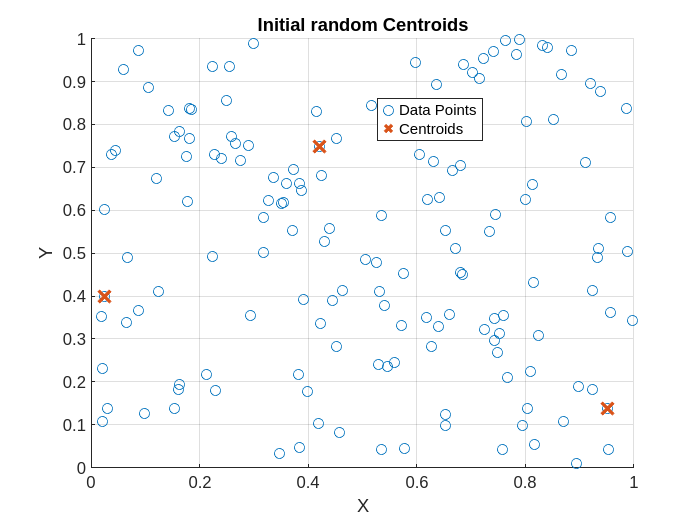

clc; clear; close all;
% Generate 150 vectors each with 2 random elements
data = rand(150, 2);

% Declare the variablek
k = 3;

% Extract k initial centroids from data
ridx = randperm(size(data, 1), k);
centroids = data(ridx, :);

% Visualization
figure;
hold on;

% Plot the data points
scatter(data(:, 1), data(:, 2), 'o', DisplayName='Data Points');

% Plot the centroids
scatter(centroids(:, 1), centroids(:, 2), 100, 'x', LineWidth=2, DisplayName='Centroids');

title('Initial random Centroids');
xlabel('X');
ylabel('Y');
legend("show", Location="best");
grid on;
hold off;

### Code Exercise (04_02)

> Compute the distance and assign to minimum distance group

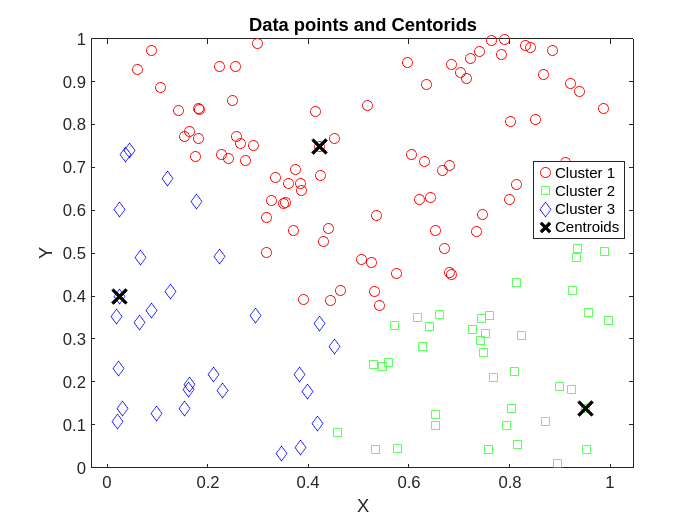

dists = zeros(size(data, 1), k);

% Calculate the squared distances
for ci = 1:k
    % Compute the squared Euclidean distance from each point to each
    % centroid and store the results in the 'dists' matrix
    dists(:, ci) = sum((data - centroids(ci, :)).^2, 2);    
end

% Find the minimum distance and the corresponding centroid for each data
% point
[minDists, assignment] = min(dists, [], 2);

% Create a new figure for visualization
figure;

% Plot each data point, colored by the index of its closest centroid
gscatter(data(:,1), data(:,2), assignment, 'rgb', 'osd');
hold on;

% Plot centroids
plot(centroids(:,1), centroids(:,2), 'kx', MarkerSize=12, LineWidth=2);

% Add title and labels
title('Data points and Centorids');
xlabel('X');
ylabel('Y');
legend([arrayfun(@(x) ['Cluster ' num2str(x)], unique(assignment), 'UniformOutput', false); 'Centroids']);

hold off;

### Code Exercise (04_03)

> Recompute the centroids as the mean of all data points within the group

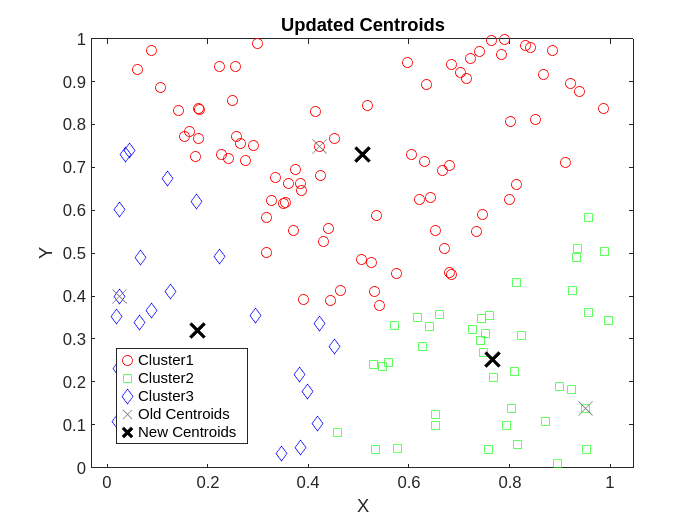

% Recalculate centroids
newCentroids = zeros(size(centroids));
for ci = 1:k
    % Calculate the mean of all points assigned to centroid ci
    newCentroids(ci, :) = mean(data(assignment == ci, :), 1);
end

% Create a new figure for updated visualizaiton 
figure;

% Plot each data point, colored by the index of its closest centroid
gscatter(data(:,1), data(:,2), assignment, 'rgb', 'osd');
hold on;

% Plot old centroids with transparent (faded) x marks
plot(centroids(:,1), centroids(:,2), 'x', MarkerSize=12, Color=[0.5 0.5 0.5 0.5]);

% Plot new centroids
plot(newCentroids(:,1), newCentroids(:,2), 'kx', MarkerSize=12, LineWidth=2);

% Add title and labels
title('Updated Centroids');
xlabel('X');
ylabel('Y');
legend([arrayfun(@(x) ['Cluster' num2str(x)], unique(assignment), UniformOutput=false); 'Old Centroids'; 'New Centroids']);
hold off;